%Load the image
image = load('abdomen.mat');
abd = image.abdomen;
roi = image.roi;
%Load dataset containing fat pixels
fat = load('fatPoints.mat');
x1 = fat.x1;
x2 = fat.x2;
y = fat.y;

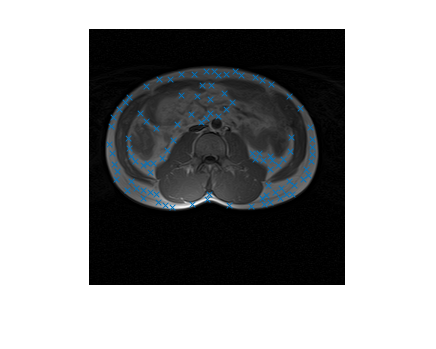

%Plot the abdominal scan together with the fat points
figure();
imshow(abd);
hold on
plot(x1, x2, 'x');
hold off;

%Perform Thin Plate Splines regression on fat points to identify regularization parameter
%lambda with 5, 10 and 20 degrees of freedom
data = [x1; x2; double(y)]';
lambdas = logspace(0, 5.3, 100);
dfList = zeros(1, length(lambdas));
for i = 1:length(lambdas)
    [~, df] = ThinPlateSplines(data, lambdas(i), 1, 1, 256);
    dfList(i) = df;
end

   1.0e+05 *

  Columns 1 through 14

         0    0.7294    0.9386    1.1454    1.4935    1.5695    1.6517    1.4123    1.2833    1.1343    0.9278    0.8049    0.7371    0.6422
    0.7294         0    0.0077    0.0300    0.1283    0.1855    0.2883    0.5816    0.6707    0.7924    0.8121    0.0226    0.0439    0.0514
    0.9386    0.0077         0    0.0046    0.0602    0.1041    0.1922    0.5075    0.6156    0.7640    0.8139    0.0149    0.0388    0.0556
    1.1454    0.0300    0.0046         0    0.0292    0.0661    0.1483    0.4979    0.6254    0.7999    0.8751    0.0280    0.0584    0.0845
    1.4935    0.1283    0.0602    0.0292         0    0.0052    0.0408    0.3360    0.4703    0.6617    0.7768    0.0651    0.0892    0.1264
    1.5695    0.1855    0.1041    0.0661    0.0052         0    0.0121    0.2441    0.3669    0.5482    0.6693    0.0867    0.1009    0.1379
    1.6517    0.2883    0.1922    0.1483    0.0408    0.0121         0    0.1369    0.2380    0.3977    0.5205    0.

[~, I5] = min(abs(dfList - 5));
[~, I10] = min(abs(dfList - 10));
[~, I20] = min(abs(dfList - 20));

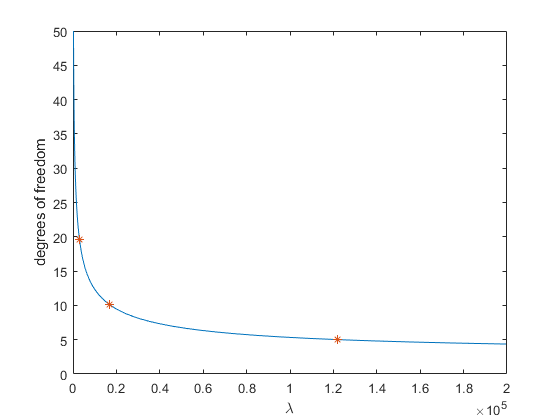

%Plot the number of degrees of freedom as a function of lambda
figure();
plot(lambdas, dfList);
hold on;
x = [lambdas(I5) lambdas(I10) lambdas(I20)];
y = [dfList(I5) dfList(I10) dfList(I20)];
plot(x, y, '*');
yticks(0:5:50);
ylim([0 50]);
xlabel("\lambda");
ylabel("degrees of freedom");
hold off;

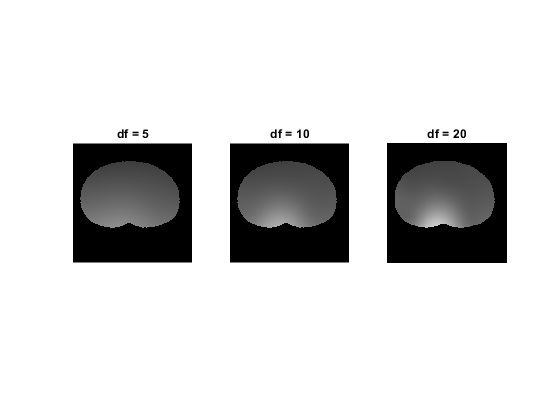

%Perform Thin Plate Splines regression with the 3 values of the
%regularization parameter
dfLambdas = [lambdas(I5), lambdas(I10), lambdas(I20)];
degreesOfFreedom = [5, 10, 20];
%Plot the 2D bias fields
figure();
for i = 1:length(dfLambdas)
    [F, ~] = ThinPlateSplines(data, dfLambdas(i), 1, 1, 256);
    F = uint8(F).*roi;
    subplot(1, 3, i);
    imshow(F), title("df = " + degreesOfFreedom(i));
end

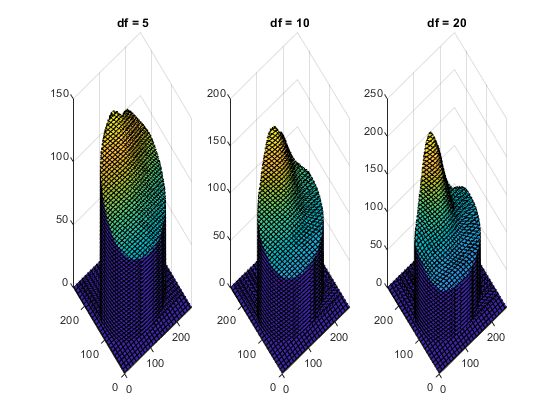

%Plot the surface plots
x = 1:1:256;
[X, Y] = meshgrid(x);
figure();
for i = 1:length(dfLambdas)
    [F, ~] = ThinPlateSplines(data, dfLambdas(i), 1, 1, 256);
    F = uint8(F).*roi;
    subplot(1, 3, i);
    surf(X, Y, F, 'LineStyle', ':'), title("df = " + degreesOfFreedom(i));
    xlim([0 256]);
    ylim([0 256]);
end

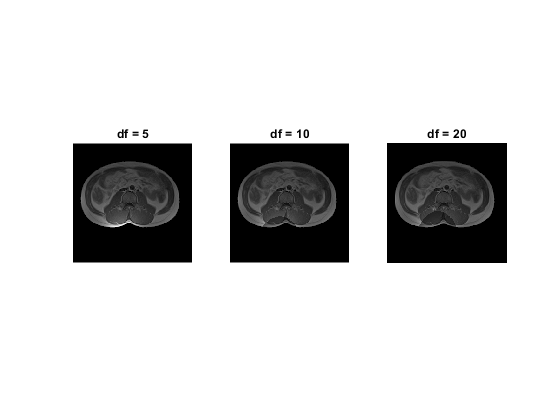

%Construct the corrected image
figure();
scFactor = 100;
for i = 1:length(dfLambdas)
    [F, ~] = ThinPlateSplines(data, dfLambdas(i), 1, 1, 256);
    F = uint8(uint8(F).*roi / scFactor);
    trueImage = abd./F;
    subplot(1, 3, i);
    imshow(trueImage.*roi), title("df = " + degreesOfFreedom(i));
end